# Visualizing Pyramid Models of Quadrat Density Maps

The following code load the 3D PM matrix created from [Quadrat_Density_PM.ipynb](http://localhost:8892/notebooks/Quadrat_Density_PM.ipynb) and visualize the PM in a 3D environment.

Visualization is created for clustered point set

## 1. Load 3D Matrices

addpath('E:/Projects/Pyramid_model/Matlab_code/function');

path_table = "E:/Projects/Pyramid_model/tables/";
path_fig = "E:/Projects/Pyramid_model/figures/";

max_intensity = readtable(path_table+"max_intensity.csv");
pnts = readtable(path_table+"sim_pnts_cluster.csv");


warning('off','all')


% ------- load the pyramids of clustered points ------------
array3D_i = load(path_table + "array3D_intensity.mat");
array3D_i = array3D_i.vect;
array3D_i = flip(array3D_i,1);

array3D_res = load(path_table + "array3D_residual.mat");
array3D_res = array3D_res.vect;
array3D_res = flip(array3D_res,1);


s = size(array3D_i);
z_scale = 0.75;

## 2. Create Pyramid Model

array3D_p = NaN(s(1),s(2),s(3)); % min-max scaling by layer
array3D_pct = NaN(s(1),s(2),s(3)); % min-max scaling by layer

for i = 1: s(3)
%for i = 100: 101

    edge = i;
    
    % ------- get only the volume in the pyramid --------
    layer = array3D_i((1+edge):(s(1)-edge),(1+edge):(s(2)-edge),i);
    %layer = array3D_i(:,:,i);
    
    % ------ convert the values in each layers into percentile scores------
    minimum = min(min(layer));
    maximum = max(max(layer));
    result = (layer - minimum)/(maximum-minimum);
    %result = layer; 
    flat_layer = reshape(layer,1,[]);
    [sorted,idx]=sort(flat_layer,'Ascend');
    sorted_flat_layer=zeros(size(sorted));
    sorted_flat_layer(idx)=1:length(sorted);
    sorted_flat_layer = sorted_flat_layer/length(flat_layer);
    result_pct=reshape(sorted_flat_layer,size(layer));
    
    array3D_p((1+edge):(s(1)-edge),(1+edge):(s(2)-edge),i) = result;
    %array3D_p(:,:,i) = result;
    array3D_pct((1+edge):(s(1)-edge),(1+edge):(s(2)-edge),i) = result_pct;
    
end

lv1=array3D_pct(:,:,1);
lv1(lv1<1)=0;
array3D_pct(:,:,1) = lv1;

## 3. Plot the maximum intensity points (clustered)

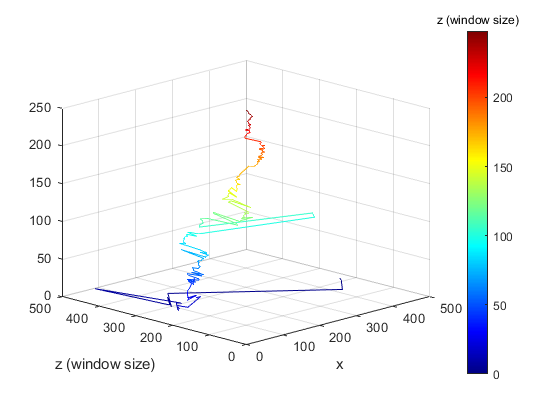

cla;
hold off;
% ax1 = subplot(3,1,1);

x = max_intensity.x;
y = 500-max_intensity.y;
z = max_intensity.z; 

%c = sub_lines.z(1).*int16(ones(height(z),1));
%figure;
%h1 = axes;
plot3(x,y,z);
patch([x.' nan],[y.' nan],[z.' nan],[z.' nan],'FaceColor','none','EdgeColor','interp');
colormap('jet');
colorbar
view(3)
%set(h1,'XDir','reverse');
%set(h1,'YDir','reverse');
%disp(min(sub_lines.z));
%patch(x, y, z, c,'EdgeColor','interp','FaceColor','none');
xlim([0 500]);
ylim([0 500]);
pbaspect([1 1 z_scale]);
grid on;

% title('Moving trajectory of densest quadrat centroid in the PM');
xlabel('x');
ylabel('y');
ylabel('z (window size)');
hcb=colorbar;
hcb.Title.String = "z (window size)";
view(-45,15);
exportgraphics(gcf,strcat(path_fig,'45-15','.png'),'Resolution',300);

## 4. Display Density Slices (clustered)

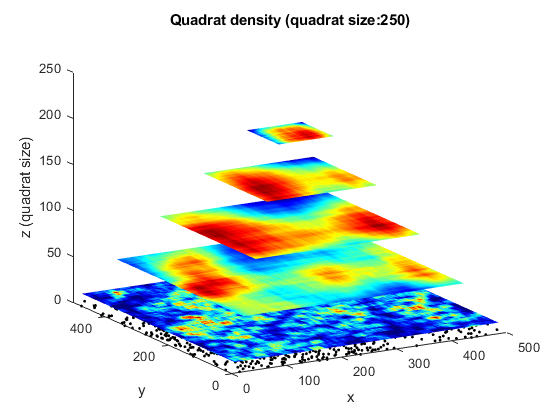

% slice_v =27
cla;
%for slice_v = [2,5,10,20,40,60,80,100,120,140,160,180,200,220,240,260]
for slice_v = [10,50,100,150,200,250]
    scatter3(pnts.x,pnts.y,pnts.y*0,5,'filled','MarkerFaceColor','black');
    hold on;
    
    sl = slice(array3D_p,[],[],slice_v,'EdgeColor','none');
    sl.EdgeColor = 'none';
    iso_value_s=num2str(slice_v);
        
    % Add the base map
    %base=array3D_p(:,:,1);
    
    view(-30,15);
    xlabel('x')
    ylabel('y')
    zlabel('z (quadrat size)')
    
    grid off
    xlim([0 500]);
    ylim([0 500]);
    zlim([0 250]);
    pbaspect([1 1 z_scale]);
    title(strcat('Quadrat density (quadrat size: ',num2str(slice_v),')'));
    drawnow;
    hold on;
    exportgraphics(gcf,strcat(path_fig,'intensity_slice',num2str(slice_v),'.png'),'Resolution',300);
end
 exportgraphics(gcf,strcat(path_fig,'intensity_slice_all2.png'),'Resolution',300);

## 5. Plot the global intensity peaks (clustered)

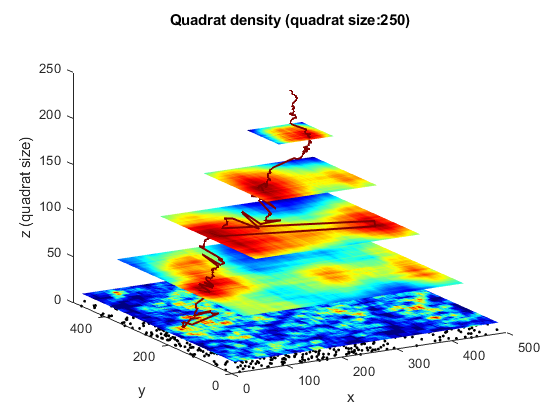

cla;
hold off;
% ax1 = subplot(3,1,1);

x = max_intensity.x;
y = 500-max_intensity.y;
z = max_intensity.z; 

plot3(x,y,z);
colormap('jet');
p = patch([x.' nan],[y.' nan],[z.' nan],[z.' nan],'FaceColor','none','EdgeColor','interp','LineWidth',1.5);
view(3);
%set(h1,'XDir','reverse');
%set(h1,'YDir','reverse');
%disp(min(sub_lines.z));
%patch(x, y, z, c,'EdgeColor','interp','FaceColor','none');

hold on;
%for slice_v = [2,5,10,20,40,60,80,100,120,140,160,180,200,220,240,260]
for slice_v = [10,50,100,150,200,250]
    scatter3(pnts.x,pnts.y,pnts.y*0,5,'filled','MarkerFaceColor','black');
    hold on;
    
    sl = slice(array3D_p,[],[],slice_v,'EdgeColor','none');
    sl.EdgeColor = 'none';
    iso_value_s=num2str(slice_v);
        
    % Add the base map
    %base=array3D_p(:,:,1);
    
    view(-30,15);
    xlabel('x')
    ylabel('y')
    zlabel('z (quadrat size)')
    
    grid off
    xlim([0 500]);
    ylim([0 500]);
    zlim([0 250]);
    pbaspect([1 1 z_scale]);
    title(strcat('Quadrat density (quadrat size: ',num2str(slice_v),')'));
    drawnow;
    hold on;
end
exportgraphics(gcf,strcat(path_fig,'quadrat_density_and_peak.png'),'Resolution',300);

## 6. Plot isosurface at one level (clustered)

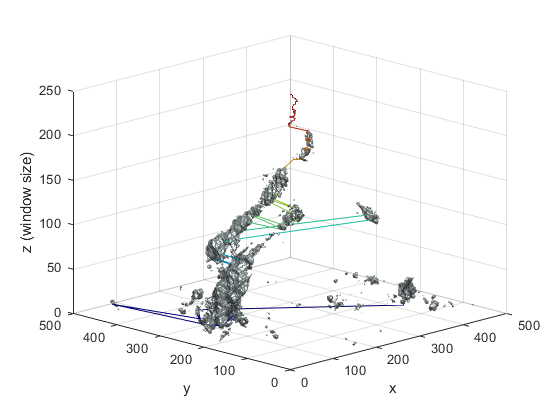

cla;
hold off;
x = max_intensity.x;
y = 500-max_intensity.y;
z = max_intensity.z; 

plot3(x,y,z);
colormap('jet');
p = patch([x.' nan],[y.' nan],[z.' nan],[z.' nan],'FaceColor','none','EdgeColor','interp');
view(3)

xlim([0 500]);
ylim([0 500]);
pbaspect([1 1 0.5]);

hold on;

% -------------------- Plot high density voxels ---------------------------

isovalue=0.99;
p=patch(isosurface(smooth3(array3D_pct,'box',3),isovalue:1));

p.FaceColor = '#99A3A4';
p.EdgeColor = 'none';
camlight('headlight'); 
lighting gouraud;
xlim([0 s(1)]);
ylim([0 s(2)]);
zlim([0 s(3)]);
xlabel('x'); 
ylabel('y');
zlabel('z (window size)');
pbaspect([1 1 z_scale]);
grid on;
view(-45,15);
exportgraphics(gcf,strcat(path_fig,'Intensity_',num2str(isovalue),'pct_45-15_L.png'),'Resolution',300);

## 7. Plot isosurface with quadrat density slices (clustered)

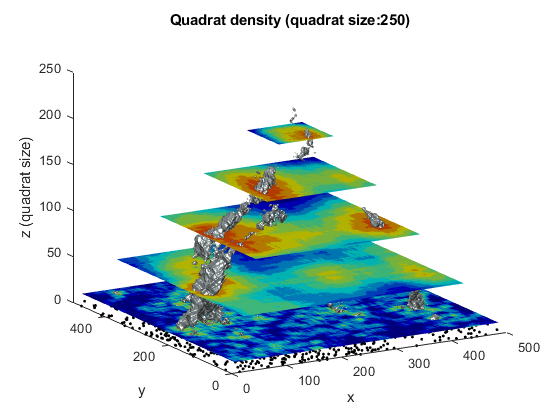

cla;

hold off;
view(3)


% -------------------- Plot high density voxels ---------------------------

isovalue=0.99;
p=patch(isosurface(smooth3(array3D_pct,'box',3),isovalue:1));

p.FaceColor = '#99A3A4';
p.EdgeColor = 'none';
camlight('headlight'); 
lighting gouraud;
xlim([0 s(1)]);
ylim([0 s(2)]);
zlim([0 s(3)]);
xlabel('x'); 
ylabel('y');
zlabel('z (window size)');
pbaspect([1 1 z_scale]);
grid on;
view(-45,15);

% ---------------- Plot slices of quadrat density -------------------------
hold on;

for slice_v = [10,50,100,150,200,250]
    scatter3(pnts.x,pnts.y,pnts.y*0,5,'filled','MarkerFaceColor','black');
    hold on;
    
    sl = slice(array3D_p,[],[],slice_v,'EdgeColor','none');
    sl.EdgeColor = 'none';
    iso_value_s=num2str(slice_v);
        
    % Add the base map
    %base=array3D_p(:,:,1);
    
    view(-30,15);
    xlabel('x')
    ylabel('y')
    zlabel('z (quadrat size)')
    
    grid off
    xlim([0 500]);
    ylim([0 500]);
    zlim([0 250]);
    pbaspect([1 1 z_scale]);
    title(strcat('Quadrat density (quadrat size: ',num2str(slice_v),')'));
    drawnow;
    hold on;
end

exportgraphics(gcf,strcat(path_fig,'voxels_with_slices.png'),'Resolution',300);